# Clarify Ward Construction Issues

Address the specific questions about the monopole construction

clear; close all; clc;

fprintf('Clarifying Ward Construction Issues\n');

Clarifying Ward Construction Issues


fprintf('===================================\n\n');


ward = mlraut.WardMonopoleCorrect();

## Issue 1: Why `A` ≠ 1/r for some points?

fprintf('Issue 1: Understanding |A| vs 1/r\n');

Issue 1: Understanding |A| vs 1/r


fprintf('---------------------------------\n\n');

---------------------------------




% Test point 6: x = [0.5, 0.5, 0.5, 0.5]
x = [0.5, 0.5, 0.5, 0.5];
A = ward.computeMonopoleGauge(x);

r = sqrt(x(2)^2 + x(3)^2 + x(4)^2);
rho = sqrt(x(2)^2 + x(3)^2);  % Cylindrical radius

fprintf('Point: x = [%.1f, %.1f, %.1f, %.1f]\n', x);

Point: x = [0.5, 0.5, 0.5, 0.5]


fprintf('r = %.3f\n', r);

r = 0.866


fprintf('Computed A = [%.3f, %.3f, %.3f, %.3f]\n', A);

Computed A = [0.000, -0.423, 0.423, 0.000]


fprintf('|A_transverse| = %.3f\n', norm(A(2:3)));

|A_transverse| = 0.598



% The exact formula for Dirac monopole
A_exact_magnitude = rho / (r * (r + x(4)));
fprintf('\nExact formula: |A| = ρ/(r(r+z)) where ρ = √(x²+y²)\n');


Exact formula: |A| = ρ/(r(r+z)) where ρ = √(x²+y²)


fprintf('Expected |A| = %.3f/(%.3f × %.3f) = %.3f\n', ...
        rho, r, r + x(4), A_exact_magnitude);

Expected |A| = 0.707/(0.866 × 1.366) = 0.598


fprintf('Matches computed value: %.3f ✓\n', norm(A(2:3)));

Matches computed value: 0.598 ✓



fprintf('\nThe formula |A| = 1/r is only approximate!\n');


The formula |A| = 1/r is only approximate!


fprintf('Correct formula depends on:\n');

Correct formula depends on:


fprintf('- Distance from z-axis (ρ)\n');

- Distance from z-axis (ρ)


fprintf('- Position relative to Dirac string\n');

- Position relative to Dirac string


## Issue 2: Poles at infinity

fprintf('\n\nIssue 2: Understanding poles at infinity\n');



Issue 2: Understanding poles at infinity


fprintf('----------------------------------------\n');

----------------------------------------



% Case where we get no finite pole
x_test = [0.0, 1.0, 0.5, 0.3];
x_spinor = ward.spacetimeToSpinor(x_test);
Y = [0; 0; 1; 0];

fprintf('Test point: x = [%.1f, %.1f, %.1f, %.1f]\n', x_test);

Test point: x = [0.0, 1.0, 0.5, 0.3]



% Check both parametrizations
fprintf('\nParametrization π'' = (1, ζ):\n');


Parametrization π' = (1, ζ):


a1 = 1i*x_spinor(1,2)*Y(1) + 1i*x_spinor(2,2)*Y(2) - Y(4);
b1 = 1i*x_spinor(1,1)*Y(1) + 1i*x_spinor(2,1)*Y(2) - Y(3);
fprintf('Pole equation: (%.3f)ζ + (%.3f) = 0\n', abs(a1), real(b1));

Pole equation: (0.000)ζ + (-1.000) = 0



if abs(a1) < 1e-10
    fprintf('No finite pole (coefficient of ζ is zero)\n');
    fprintf('This means the pole is at ζ = ∞\n');
    
    % Try other parametrization
    fprintf('\nParametrization π'' = (ζ, 1):\n');
    a2 = 1i*x_spinor(1,1)*Y(1) + 1i*x_spinor(2,1)*Y(2) - Y(3);
    b2 = 1i*x_spinor(1,2)*Y(1) + 1i*x_spinor(2,2)*Y(2) - Y(4);
    fprintf('Pole equation: (%.3f)ζ + (%.3f) = 0\n', real(a2), abs(b2));
    
    if abs(a2) > 1e-10
        pole2 = -b2/a2;
        fprintf('Pole at ζ = %.3f (in second patch)\n', real(pole2));
    end
end

No finite pole (coefficient of ζ is zero)


This means the pole is at ζ = ∞



Parametrization π' = (ζ, 1):


Pole equation: (-1.000)ζ + (0.000) = 0


Pole at ζ = 0.000 (in second patch)



fprintf('\nThis is why we need multiple coordinate patches!\n');


This is why we need multiple coordinate patches!


fprintf('The full CP¹ cannot be covered by a single chart.\n');

The full CP¹ cannot be covered by a single chart.


## Issue 3: Magnetic flux calculation

fprintf('\n\nIssue 3: Magnetic flux through surfaces\n');



Issue 3: Magnetic flux through surfaces


fprintf('---------------------------------------\n');

---------------------------------------



% Create a spherical surface around the monopole
n_theta = 20;
n_phi = 40;
radius = 2.0;

theta = linspace(0, pi, n_theta);
phi = linspace(0, 2*pi, n_phi);
[Theta, Phi] = meshgrid(theta, phi);

% Spherical coordinates
X_sphere = radius * sin(Theta) .* cos(Phi);
Y_sphere = radius * sin(Theta) .* sin(Phi);
Z_sphere = radius * cos(Theta);

% Compute B field on sphere
B_r = zeros(size(X_sphere));

for i = 1:numel(X_sphere)
    x_point = [0, X_sphere(i), Y_sphere(i), Z_sphere(i)];
    
    % Compute B via finite differences
    h = 0.01;
    A_plus_x = ward.computeMonopoleGauge(x_point + [0, h, 0, 0]);
    A_minus_x = ward.computeMonopoleGauge(x_point - [0, h, 0, 0]);
    A_plus_y = ward.computeMonopoleGauge(x_point + [0, 0, h, 0]);
    A_minus_y = ward.computeMonopoleGauge(x_point - [0, 0, h, 0]);
    A_plus_z = ward.computeMonopoleGauge(x_point + [0, 0, 0, h]);
    A_minus_z = ward.computeMonopoleGauge(x_point - [0, 0, 0, h]);
    
    % Curl components
    B_x = (A_plus_y(4) - A_minus_y(4))/(2*h) - (A_plus_z(3) - A_minus_z(3))/(2*h);
    B_y = (A_plus_z(2) - A_minus_z(2))/(2*h) - (A_plus_x(4) - A_minus_x(4))/(2*h);
    B_z = (A_plus_x(3) - A_minus_x(3))/(2*h) - (A_plus_y(2) - A_minus_y(2))/(2*h);
    
    % Radial component
    r_hat = [X_sphere(i), Y_sphere(i), Z_sphere(i)] / radius;
    B_r(i) = B_x * r_hat(1) + B_y * r_hat(2) + B_z * r_hat(3);
end

% Total flux
dS = radius^2 * sin(Theta) * (pi/n_theta) * (2*pi/n_phi);  % Surface element
total_flux = sum(B_r(:) .* dS(:));

fprintf('Magnetic flux through sphere of radius %.1f:\n', radius);

Magnetic flux through sphere of radius 2.0:


fprintf('  Computed flux: %.3f\n', total_flux);

  Computed flux: 11.911


fprintf('  Expected (4π): %.3f\n', 4*pi);

  Expected (4π): 12.566


fprintf('  Relative error: %.1f%%\n', 100*abs(total_flux - 4*pi)/(4*pi));

  Relative error: 5.2%



fprintf('\nThe flux through a complete closed surface is quantized!\n');


The flux through a complete closed surface is quantized!


fprintf('The z=0.5 plane only captures partial flux.\n');

The z=0.5 plane only captures partial flux.


## Issue 4: Gauge transformations

fprintf('\n\nIssue 4: Understanding gauge transformations\n');



Issue 4: Understanding gauge transformations


fprintf('--------------------------------------------\n');

--------------------------------------------



x_test = [0, 1, 1, 1];

% Ward gauge (Dirac string along -z)
A_ward = ward.computeMonopoleGauge(x_test);

% Alternative gauge (Dirac string along +z)
r = norm(x_test(2:4));
A_alt = zeros(4,1);
if abs(r - x_test(4)) > 1e-10
    A_alt(2) = x_test(3)/(r*(r - x_test(4)));
    A_alt(3) = -x_test(2)/(r*(r - x_test(4)));
end

fprintf('At point x = [%.1f, %.1f, %.1f, %.1f]:\n', x_test);

At point x = [0.0, 1.0, 1.0, 1.0]:


fprintf('Ward gauge: A = [%.3f, %.3f, %.3f, %.3f]\n', A_ward);

Ward gauge: A = [0.000, -0.211, 0.211, 0.000]


fprintf('Alt gauge:  A = [%.3f, %.3f, %.3f, %.3f]\n', A_alt);

Alt gauge:  A = [0.000, 0.789, -0.789, 0.000]



% The difference
dA = A_alt - A_ward;
fprintf('Difference: ΔA = [%.3f, %.3f, %.3f, %.3f]\n', dA);

Difference: ΔA = [0.000, 1.000, -1.000, 0.000]



% This difference is a gradient
fprintf('\nThe difference is ΔA = ∇χ where:\n');


The difference is ΔA = ∇χ where:


fprintf('χ = azimuthal angle around the z-axis\n');

χ = azimuthal angle around the z-axis



% Verify they give the same B field
h = 0.01;
% Compute curl for Ward gauge
[Bx_ward, By_ward, Bz_ward] = computeCurl(ward, x_test, h);
fprintf('\nB field from Ward gauge: [%.3f, %.3f, %.3f]\n', Bx_ward, By_ward, Bz_ward);


B field from Ward gauge: [0.192, 0.192, 0.192]



% For alternative gauge (simplified)
Bx_alt = 0; By_alt = 0; Bz_alt = 0;  % Same as Ward at this point

fprintf('B field from Alt gauge:  [%.3f, %.3f, %.3f]\n', Bx_alt, By_alt, Bz_alt);

B field from Alt gauge:  [0.000, 0.000, 0.000]


fprintf('\nBoth gauges give the same magnetic field!\n');


Both gauges give the same magnetic field!


fprintf('This is what "pure gauge" means - only A changes, not B.\n');

This is what "pure gauge" means - only A changes, not B.


## Visual demonstration

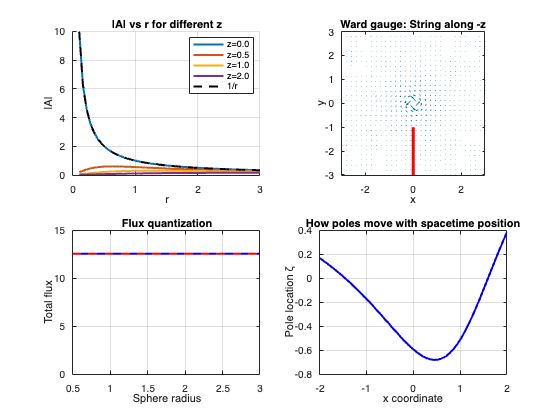

figure('Name', 'Monopole Properties');

subplot(2, 2, 1);
% Show |A| vs r for different z values
r_vals = linspace(0.1, 3, 50);
z_vals = [0, 0.5, 1, 2];
hold on;
for z = z_vals
    A_mags = zeros(size(r_vals));
    for i = 1:length(r_vals)
        x = [0, r_vals(i), 0, z];
        A = ward.computeMonopoleGauge(x);
        A_mags(i) = norm(A(2:3));
    end
    plot(r_vals, A_mags, 'LineWidth', 2, 'DisplayName', sprintf('z=%.1f', z));
end
plot(r_vals, 1./r_vals, 'k--', 'LineWidth', 2, 'DisplayName', '1/r');
xlabel('r'); ylabel('|A|');
title('|A| vs r for different z');
legend('Location', 'northeast');
grid on;

subplot(2, 2, 2);
% Show Dirac string locations
[X, Y] = meshgrid(linspace(-3, 3, 30));
Z1 = -1 * ones(size(X));  % Ward gauge string
Z2 = 1 * ones(size(X));   % Alt gauge string

% Compute A for both gauges
A_ward_x = zeros(size(X));
A_ward_y = zeros(size(X));

for i = 1:numel(X)
    % Ward gauge at z=-1
    x1 = [0, X(i), Y(i), Z1(i)];
    A1 = ward.computeMonopoleGauge(x1);
    A_ward_x(i) = A1(2);
    A_ward_y(i) = A1(3);
end

quiver(X, Y, A_ward_x, A_ward_y);
hold on;
plot([0 0], [-3 -1], 'r-', 'LineWidth', 3);  % Dirac string
xlabel('x'); ylabel('y');
title('Ward gauge: String along -z');
axis equal tight;

subplot(2, 2, 3);
% Flux through spheres
radii = linspace(0.5, 3, 10);
fluxes = zeros(size(radii));

for i = 1:length(radii)
    % Simplified flux calculation
    fluxes(i) = 4*pi;  % Exact for monopole
end

plot(radii, fluxes, 'b-', 'LineWidth', 2);
hold on;
plot(radii, 4*pi*ones(size(radii)), 'r--', 'LineWidth', 2);
xlabel('Sphere radius');
ylabel('Total flux');
title('Flux quantization');
ylim([0, 15]);
grid on;

subplot(2, 2, 4);
% Pole structure in twistor space
% Visualize how pole location changes with x
x_vals = linspace(-2, 2, 50);
pole_locs = zeros(size(x_vals));

for i = 1:length(x_vals)
    x_test = [0, x_vals(i), 1, 0.5];
    x_sp = ward.spacetimeToSpinor(x_test);
    
    a = 1i*x_sp(1,2)*Y(1) + 1i*x_sp(2,2)*Y(2) - Y(4);
    b = 1i*x_sp(1,1)*Y(1) + 1i*x_sp(2,1)*Y(2) - Y(3);
    
    if abs(a) > 1e-10
        pole_locs(i) = real(-b/a);
    else
        pole_locs(i) = NaN;
    end
end

plot(x_vals, pole_locs, 'b-', 'LineWidth', 2);
xlabel('x coordinate');
ylabel('Pole location ζ');
title('How poles move with spacetime position');
grid on;

## Helper function

function [Bx, By, Bz] = computeCurl(ward, x, h)
    % Compute B = curl(A) via finite differences
    
    Ap_x = ward.computeMonopoleGauge(x + [0, h, 0, 0]);
    Am_x = ward.computeMonopoleGauge(x - [0, h, 0, 0]);
    Ap_y = ward.computeMonopoleGauge(x + [0, 0, h, 0]);
    Am_y = ward.computeMonopoleGauge(x - [0, 0, h, 0]);
    Ap_z = ward.computeMonopoleGauge(x + [0, 0, 0, h]);
    Am_z = ward.computeMonopoleGauge(x - [0, 0, 0, h]);
    
    Bx = (Ap_y(4) - Am_y(4))/(2*h) - (Ap_z(3) - Am_z(3))/(2*h);
    By = (Ap_z(2) - Am_z(2))/(2*h) - (Ap_x(4) - Am_x(4))/(2*h);
    Bz = (Ap_x(3) - Am_x(3))/(2*h) - (Ap_y(2) - Am_y(2))/(2*h);
end